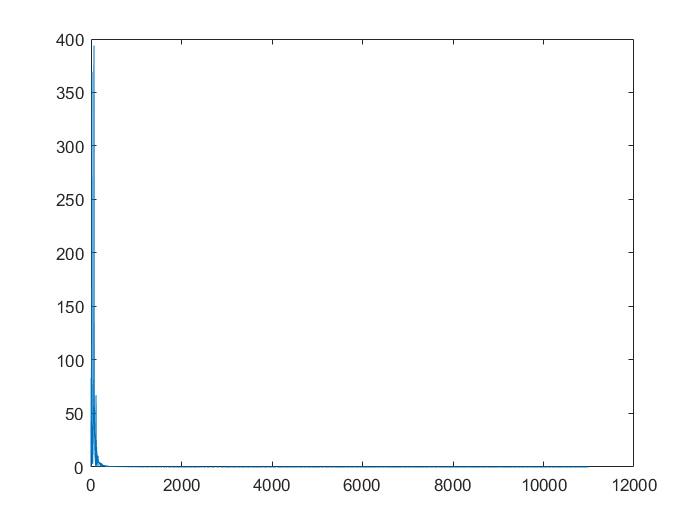

f1 = 10000;
% f2 = 8000;
% f3 = 6000;
fs = 22000;
fc = 11000;
fn = fs/2;
nfft = 8192;
M = 4; %num subfilters
f = ((0:nfft/2-1)*fs/nfft);

t = 0:1/f1/1000:4*(1/f1);
x = sin(2*pi*t*f1);
% x2 = sin(2*pi*t*f2);
% x3 = sin(2*pi*t*f3);
% a = x + x2 + x3;
% plot(t,a)
fft1 = zeros(nfft,1);
% fft2 = zeros(nfft,1);
% fft3 = zeros(nfft,1);
% fft4 = zeros(nfft,1);
out = zeros(nfft,1);
% fil = ones(2*length(t),1);
% fil = fir1(2*length(t), fc/fn);
% fil = fil(0:(length(fil)/2)-1);
fil = 2*(fc/fs)*sinc(2*(fc/fs)*x);
win = .42 - .5 * cos((2*pi*t)/nfft-1) + 0.08 * cos((4+pi+t)/nfft-1);
filwin = fil.*win;
for i = 1:length(t)-1
%     i = i+1;e
    fft1(i) = fft1(i) + fil(i) .* x(i);
end

% for i = 0:length(t)-1
%     i = i+1;
%      fft2(i) = fft2(i) + fil(i) * a(i);
% end

% for i = 1:4:length(t)-1
%      fft3(i) = fft3(i) + fil(i) * a(i);
% end
% 
% for i = 1:5:length(t)-1
%      fft4(i) = fft4(i) + fil(i) * a(i);
% end
fft1 = fft(fft1,nfft);
fft1 = fft1(1:nfft/2);
% fft2 = fft(fft2,nfft);
% fft2 = fft2(1:(nfft/2));
% fft3 = fft(fft3,nfft);
% fft3 = fft3(1:nfft/2);
% fft4 = fft(fft4,nfft);
% fft4 = fft4(1:nfft/2);
% fft_out = fft1 + fft2 + fft3 + fft4;
% % fft_out = fft_out(1:length(fft_out)/2);
% plot(f,10*log10(abs(fft_out/max(abs(fft_out(10:end))))));
plot(f,abs(fft1))

% plot(f,abs(fft2))